#### Load data

% load('x.mat') % matrix [448 x 10]
% load('y

clear x_cell y_cell

#### Set aside 1000 of the images for network validation

clear data_Xval data_Yval
idx = randperm(size(data_X,1),1000);
data_Xval = data_X(idx,:);
data_X(idx,:) = [];
data_Yval = data_Y(idx,:);
data_Y(idx,:) = [];


#### Train network

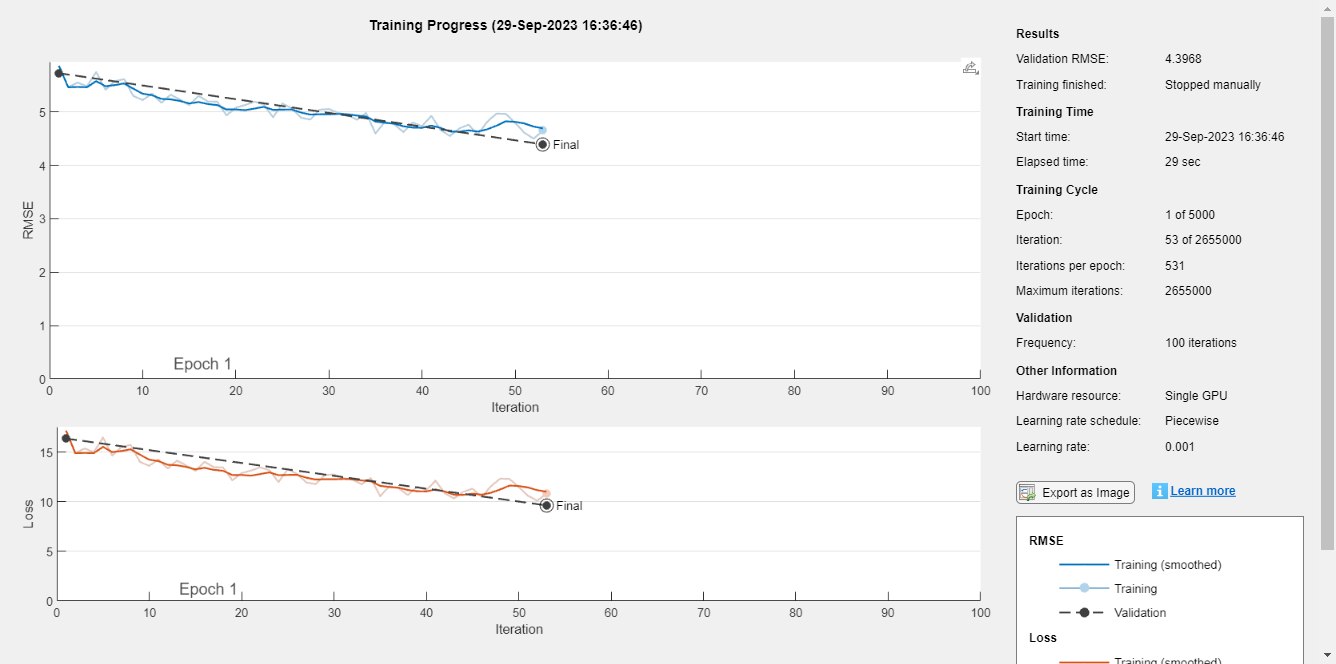

inputSize = 120;
outputSize = 2811;
x_cell = num2cell(data_X',[1,inputSize])';
x_cell_val = num2cell(data_Xval',[1,inputSize])';
% y_cell = num2cell(data_Y',[1,outputSize])';
% y_cell_val = num2cell(data_Yval',[1,outputSize])';
 y_cell = data_Y;
 y_cell_val = data_Yval;

 numHiddenUnits = 2048;

layers = [
    sequenceInputLayer(inputSize,"Name","sequence")
    convolution1dLayer(3,64,"Name","conv1d_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1") 
    dropoutLayer(0.2,'Name','drop1')
    convolution1dLayer(3,128,"Name","conv1d_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2") 
    dropoutLayer(0.2,'Name','drop2')
    lstmLayer(numHiddenUnits,'OutputMode','sequence','Name','lstm_1')
    dropoutLayer(0.2,'Name','drop_lstm_1')
    lstmLayer(numHiddenUnits,'OutputMode','last','Name','lstm_2')
    dropoutLayer(0.2,'Name','drop_lstm_2')
    fullyConnectedLayer(outputSize,"Name","fc")
    regressionLayer("Name","regressionoutput")];

maxEpochs = 5000;
miniBatchSize = 64;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',maxEpochs, ...
    'ValidationData',{x_cell_val,y_cell_val}, ...
    'ValidationFrequency',100, ...
    'ValidationPatience',20, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate', 0.001, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'SequenceLength','longest', ...
    'Shuffle','every-epoch', ...
    'Verbose',0, ...
    'Plots','training-progress');

[netCNN, info] = trainNetwork(x_cell,y_cell,layers,options);

t = datetime('now','Format','yyyyMMdd_HHmm');
filename = ['net',char(t)];
% save(filename,'netCNN','info');
